clear, clc

## LOAD FINAL PARAMETERS (DIFFERENT TRIALS)

MVC = '30';
trials = 5;
for ii = 1:trials
    trial{1,ii} = num2str(ii);
end
ErrFnc = 'moo';
OptAlg = 'godlike';
model = 'bestparameters_new';
path = 'D:\University programming\MATLAB\Module 12\Neuron Parameter Estimation\Optimazed Parameters';

for i = 1:trials
    name = [MVC '_' trial{i} '_' OptAlg '_' ErrFnc '_' model];
    data(i) = load([path '\' name '.mat']);
end
clear path, clear names, clear i

## LOAD FINAL PARAMETERS (MULTIPLE COPIES)

MVC = '10';
Trial = '2';
trials = 10;
for ii = 1:trials
    trial{1,ii} = num2str(ii);
end
ErrFnc = 'moo';
OptAlg = 'godlike';
model = 'bestparameters_new';
path = 'D:\University programming\MATLAB\Module 12\Neuron Parameter Estimation\Optimazed Parameters\Copies';

for i = 1:trials
    name = [MVC '_' Trial '_' OptAlg '_' ErrFnc '_' model '_' trial{i}];
    data(i) = load([path '\' name '.mat']);
end
clear path, clear names, clear i

## COMPARE ERRORS PER TRIAL

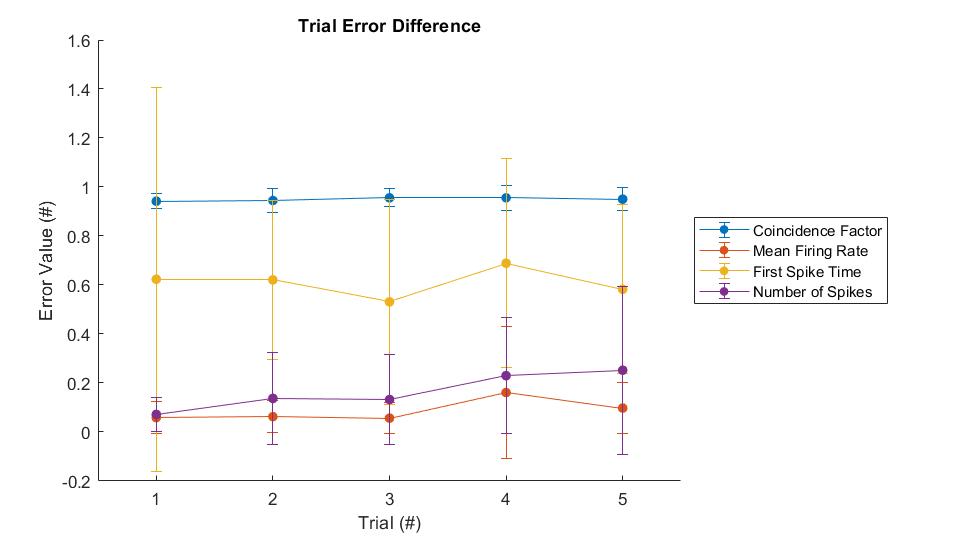

figure, clf, hold on
for i = 1:trials
    for ii = 1:length(data(i).Neuron)
        for j = 1:4
            errors_neurons(j,ii) = data(i).Neuron(ii).bestFactor(j);
        end
    end
    for j = 1:4
        errors_trial_mean(j,i) = mean(errors_neurons(j,:));
        errors_trial_std(j,i) = std(errors_neurons(j,:));
    end
end
for j = 1:4
    errorbar(errors_trial_mean(j,:),errors_trial_std(j,:),'.-','MarkerSize',20)
end
xticks(0:trials)
xlim([0.5,trials+0.5])
xlabel('Trial (#)')
ylabel('Error Value (#)')
legend({'Coincidence Factor','Mean Firing Rate','First Spike Time','Number of Spikes'},'Location','eastoutside')
title('Trial Error Difference')
set(gcf, 'units', 'normalized');
set(gcf, 'Position', [0, 0, 0.5, 0.5]);

## SAVE

path = 'D:\University programming\MATLAB\Module 12\Neuron Parameter Estimation\Errors';
name = [MVC '_MVC'];
save([path '\' name '.mat'],'errors_trial_mean')
clear path, clear name

## LOAD 

path = 'D:\University programming\MATLAB\Module 12\Neuron Parameter Estimation\Errors';
mvcs = 7;
for i = 1:mvcs
    name = [num2str(i*10) '_MVC'];
    data(i) = load([path '\' name '.mat']);
end
clear path, clear names, clear i

## COMPARE ERRORS PER MVC

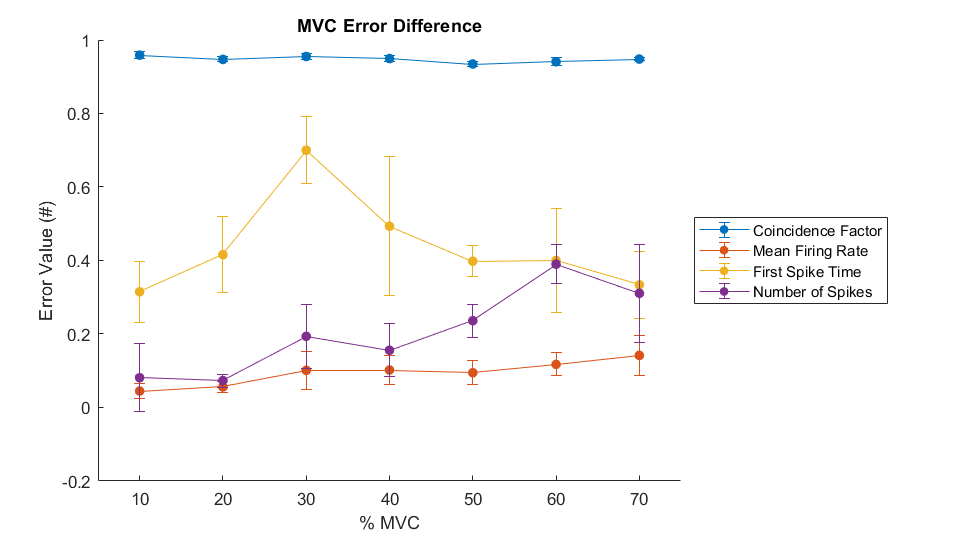

figure, clf, hold on
for i = 1:mvcs
    for j = 1:4
        errors_trial_mean(j,i) = mean(data(i).errors_trial_mean(j,:));
        errors_trial_std(j,i) = std(data(i).errors_trial_mean(j,:));
    end
end
for j = 1:4
    errorbar(errors_trial_mean(j,:),errors_trial_std(j,:),'.-','MarkerSize',20)
end
xticks(0:mvcs)
xticklabels({'','10','20','30','40','50','60','70'})
xlim([0.5,mvcs+0.5])
xlabel('% MVC')
ylabel('Error Value (#)')
legend({'Coincidence Factor','Mean Firing Rate','First Spike Time','Number of Spikes'},'Location','eastoutside')
title('MVC Error Difference')
set(gcf, 'units', 'normalized');
set(gcf, 'Position', [0, 0, 0.5, 0.5]);